# Linear System - Modeling and Simulation

## Time-invariant Discrete-time Linear System

           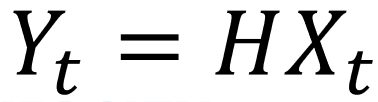

- **X: State**

- **F: System matrix**

- **u: Input**

- **G: Control matrix**

- **Y: Measurement**

- **H: Measurement matrix**

## **Linear Model – Constant Acceleration (CA)**

### **problem discription**

The simulation targets are a** dynamic state vector (position, velocity)** of a vehicle on two-dimension space (X and Y).

The **range sensor** located at origin, which can measure **the position of a vehicle**. 

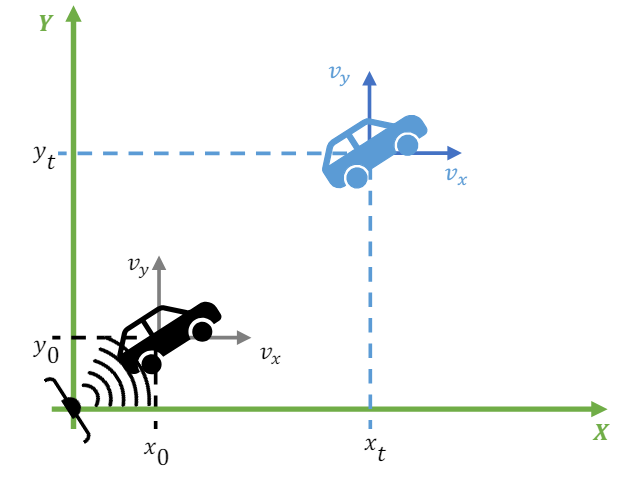

### Motion model - Constant Acceleration (CA)

A discrete vehicle motion model with acceleration inputs can be represented as follow:

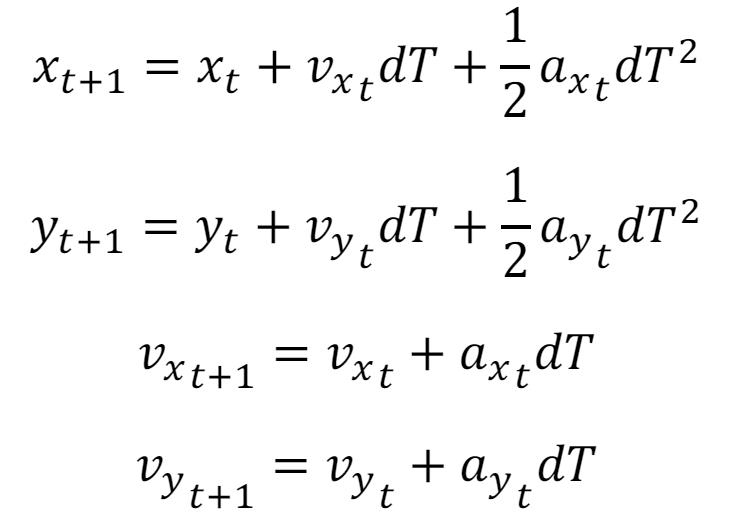

- x_t , y_t : vehicle's X and Y **position** at t

- v_x_t, v_y_t : vehicle's X and Y **velocity** at t

- a_x_t, a_y_t: vehicle's X and Y **acceleration** **input** at t

- dT: **sampling time**

### **State Space Euation**

#### System time propagation

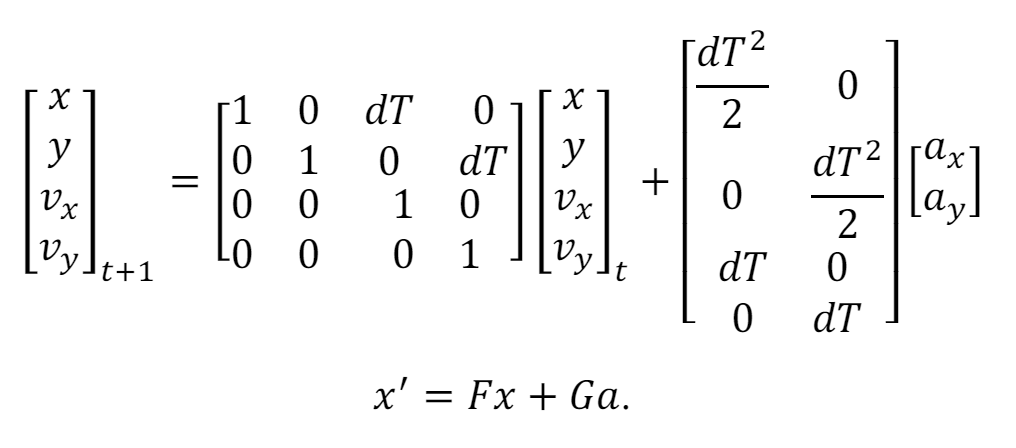

clear; close all;
% Load data for linear system practice
load('linear_system_mat_file.mat');


% To Do 
    % fill the matrix 

F =[1 0 delta_t 0 ;...
    0 1 0 delta_t ;...
    0 0 1 0 ;
    0 0 0 1 ];

G = [delta_t^2/2 0; ...
     0 delta_t^2/2; ...
     delta_t 0; ...
     0 delta_t];

#### Output

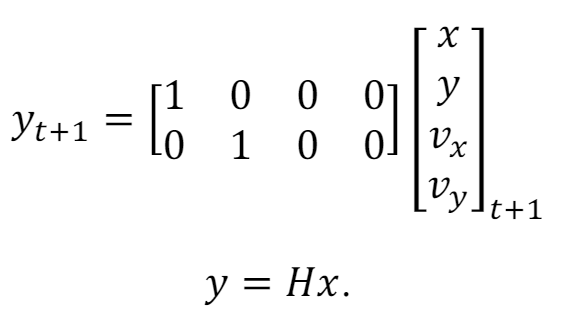

H = [1 0 0 0;...
     0 1 0 0];

### Simulation - CA, Linear model

#### Initial condition

- ∆t: 0.1 second

- initial velocity vx = 0.0 m/s, vy = 0.0 m/s

- initial positoin x = 1 m, y = 1 m

- simulation time: 0 to 30 seconds

#### Input generation

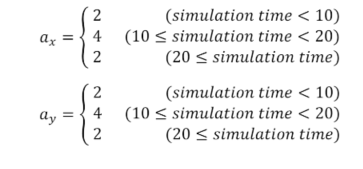

Input

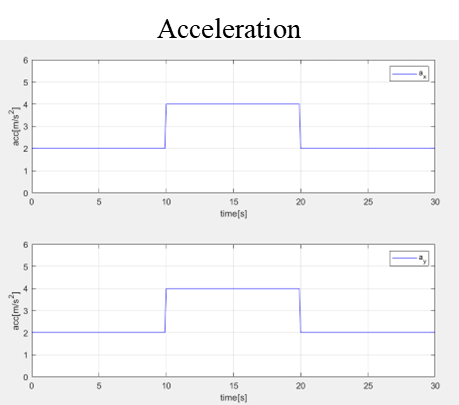

Target (Grount Truth, GT) state

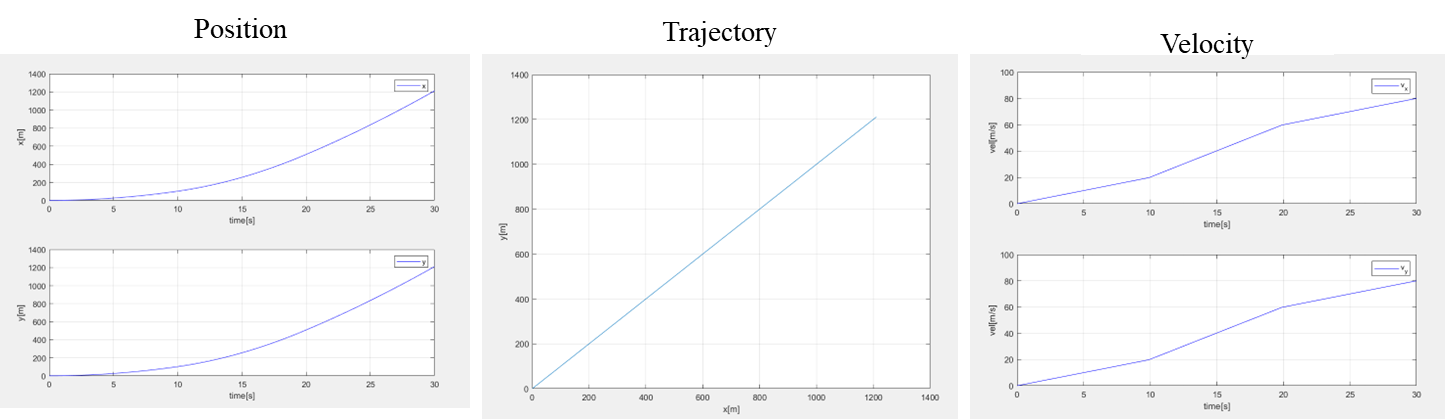

### **Simulate the state and measurement during 0 to 30 seconds,**

STATE_ORDER = 4; % [position x, position y, velocity x, velocity y]
OUTPUT_ORDER = 2; % [position x, position y]

state = zeros([STATE_ORDER, total_process_steps]);
output = zeros([OUTPUT_ORDER, total_process_steps]);

isFirstStep = true;

for idx=1:total_process_steps
    if isFirstStep == true
        % To do 
            % fill the initial state
        state(:,idx) = [position(1,idx); position(2,idx); velocity(1,idx); velocity(2,idx)];
        
        isFirstStep = false;
    else
        % To do 
            % fill the state using F, G and input matrix
        state(:,idx) = F*state(:,idx-1)+G*acceleration(:,idx-1);
    end
    % To do 
        % fill the state using state and H matrix
    output(:,idx) = H*state(:,idx);
end


## Visualize Result

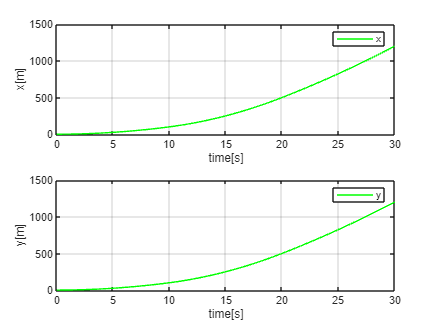

figure('Name','Constant Acceleration Model - Simulated Position','Position',[100,100,840,630]);

hold on; 

subplot(2,1,1)
plot(time, output(1,:), 'g');
legend('x'); 
xlabel('time[s]'); ylabel('x[m]'); grid on;

subplot(2,1,2)
plot(time, output(2,:), 'g');
legend('y');
xlabel('time[s]'); ylabel('y[m]'); grid on;

hold off

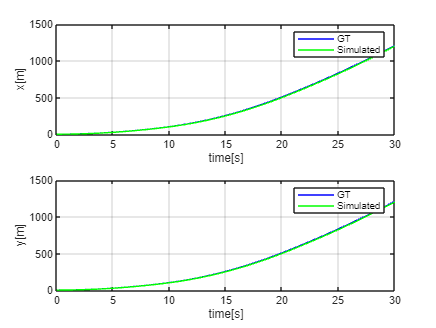


figure('Name','Comapre True Position - Simulated Position','Position',[100,100,840,630]);

hold on; 

subplot(2,1,1)
plot(time, position(1,:), 'b', time, output(1,:), 'g');
legend('GT', 'Simulated'); 
xlabel('time[s]'); ylabel('x[m]'); grid on;

subplot(2,1,2)
plot(time, position(2,:), 'b', time, output(2,:), 'g');
legend('GT', 'Simulated');
xlabel('time[s]'); ylabel('y[m]'); grid on;

hold off